# Final Project

**How to use the template**

There are many organize and communicate your results. To help ensure your peer-reviewers can accurately grade your report, this report includes the titles for the 4 required sections in Heading 1 style. Each required element for a given section has a Heading 2 area for you to place the final result. 

Make sure to place your required findings in the appropiate area for your peer-reviewer to easily find them.

Also, only the heading titles are present.* The script is not broken into sections*.

## Background and Scope

### Import the Data

You may use an import function. If not using an import function, include the code used to import the data (it may be generated from the Import Tool)

events=StormEvents2017finalProject;
monthOrder=["January", "February", "March", "April", "May", "June", "July",...
    "August", "September", "October", "November", "December"];
events.Month=reordercats(events.Month,monthOrder);
events.Property_Cost(ismissing(events.Property_Cost))=0;
events.Crop_Cost(ismissing(events.Crop_Cost))=0;
events.Damage_Property(ismissing(events.Damage_Property))=0;
events.Damage_Crops(ismissing(events.Damage_Crops))=0;
events.Total_Damage=events.Crop_Cost+events.Property_Cost;
events=removevars(events,{'Episode_Narrative','Event_Narrative'});

### Two States Most Impacted by Harvey

Clearly state the two states in order 

mostimpacted=events(events.CZ_Name=="HARVEY",:)

mostimpacted = 16×23 table
    EpisodeID      Event_ID     State     Year    Month       Event_Type        CZ_Name      Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon    Total_Damage
    __________    __________    ______    ____    _____    _________________    _______    _____________

mostimpacted=groupsummary(mostimpacted,"State","median","Total_Damage")

mostimpacted = 1×3 table
    State     GroupCount    median_Total_Damage
    ______    __________    ___________________

    KANSAS        16                 0         


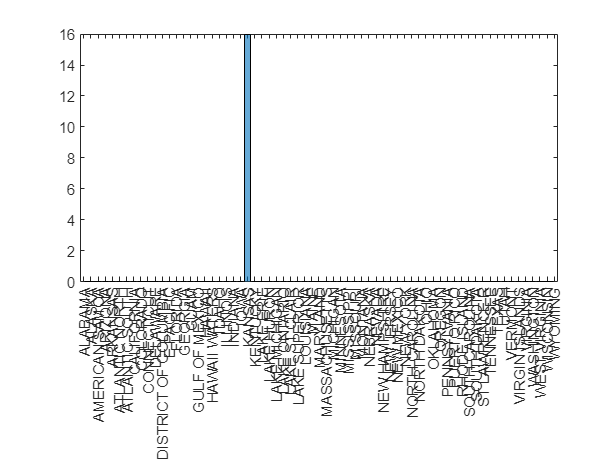

mostimpacted=events(events.CZ_Name=="HARVEY",:);
histogram(mostimpacted.State)

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

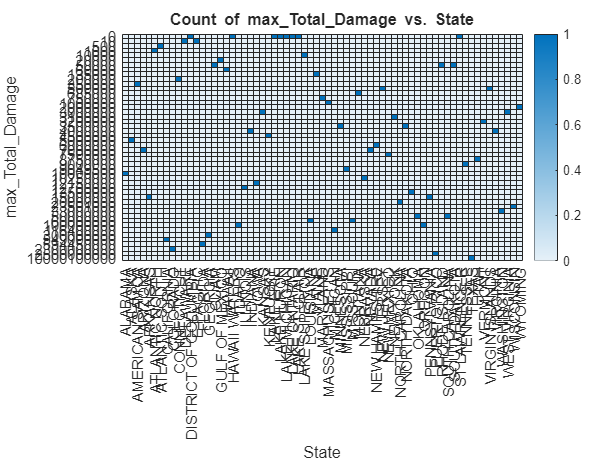

mostimpact=groupsummary(events,'State','max','Total_Damage');
heatmap(mostimpact,"State","max_Total_Damage")

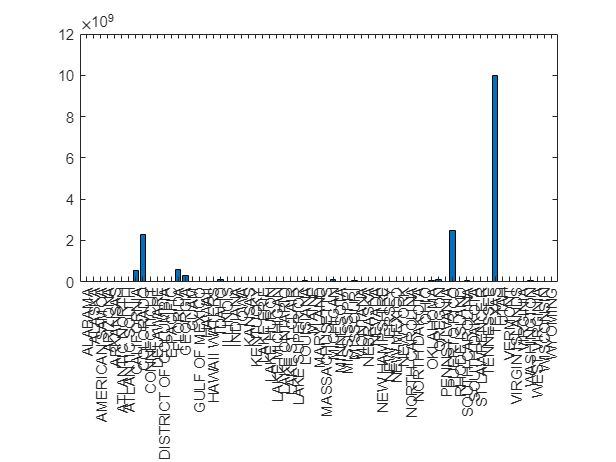

bar(mostimpact.State,mostimpact.max_Total_Damage)

## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

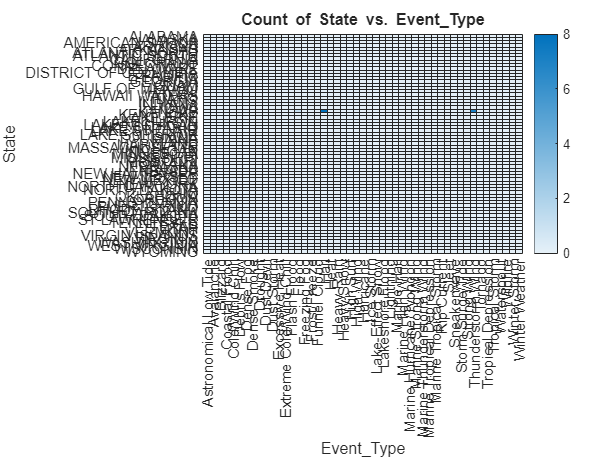

mostimpacted=events(events.CZ_Name=="HARVEY",:);
heatmap(mostimpacted,"Event_Type","State")

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

group=groupsummary(events,"State","Max","Total_Damage");
group=group(1:2,:)

group = 2×3 table
     State     GroupCount    max_Total_Damage
    _______    __________    ________________

    ALABAMA       1300            1e+07      
    ALASKA         231            5e+06      


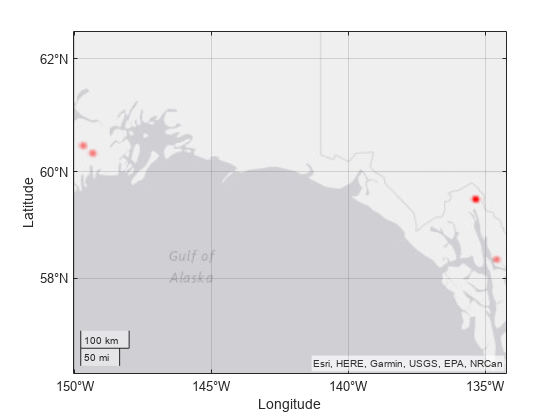

group2=events(events.State=="ALASKA",:);
% geolimits([17.0 55.2],[-128.0 -65.6])
geodensityplot(group2.Begin_Lat,group2.Begin_Lon,FaceColor="r")

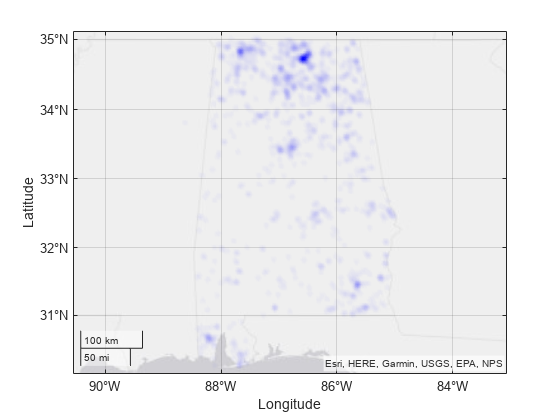

% hold on
group3=events(events.State=="ALABAMA",:);
geodensityplot(group3.Begin_Lat,group3.Begin_Lon,'FaceColor',"b")

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

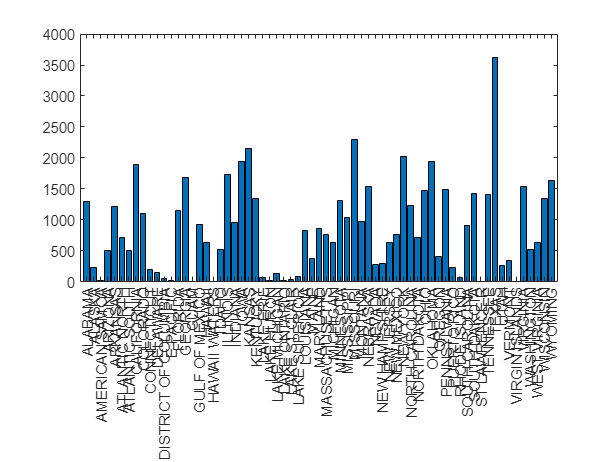

mostevents=groupsummary(events,"State","sum","Total_Damage");
bar(mostevents.State,mostevents.GroupCount)

mostevents(mostevents.GroupCount==max(mostevents.GroupCount),:)

ans = 1×3 table
    State    GroupCount    sum_Total_Damage
    _____    __________    ________________

    TEXAS       3628          7.7882e+10   


### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

[a,b]=sort(mostevents.GroupCount,"descend");
mostevents(mostevents.GroupCount==a(3) | mostevents.GroupCount==a(2) | mostevents.GroupCount==a(1),:)

ans = 3×3 table
     State      GroupCount    sum_Total_Damage
    ________    __________    ________________

    KANSAS         2153          1.2902e+07   
    MISSOURI       2289           1.562e+08   
    TEXAS          3628          7.7882e+10   


### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

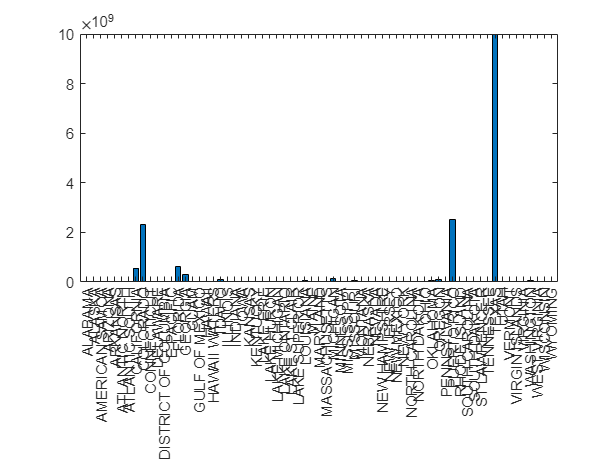

maxproperty=groupsummary(events,"State","max","Property_Cost");
bar(maxproperty.State,maxproperty.max_Property_Cost)

New

[c,d]=sort(maxproperty.GroupCount,"descend");
maxproperty(maxproperty.GroupCount==c(3) | maxproperty.GroupCount==c(2) | maxproperty.GroupCount==c(1),:)

ans = 3×3 table
     State      GroupCount    max_Property_Cost
    ________    __________    _________________

    KANSAS         2153             3e+06      
    MISSOURI       2289             6e+07      
    TEXAS          3628             1e+10      


The state with the highest property costs is Texas

maxproperty(maxproperty.GroupCount==c(1),:)

ans = 1×3 table
    State    GroupCount    max_Property_Cost
    _____    __________    _________________

    TEXAS       3628             1e+10      


### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

maxproperty(maxproperty.GroupCount==c(1) | maxproperty.GroupCount==c(2) | maxproperty.GroupCount==c(3),:)

ans = 3×3 table
     State      GroupCount    max_Property_Cost
    ________    __________    _________________

    KANSAS         2153             3e+06      
    MISSOURI       2289             6e+07      
    TEXAS          3628             1e+10      


Second city is:

maxproperty(maxproperty.GroupCount==c(2),:)

ans = 1×3 table
     State      GroupCount    max_Property_Cost
    ________    __________    _________________

    MISSOURI       2289             6e+07      


## Conclusions and Recommendation

According to conclusion most impacted city is Texas.It costs too much.We can support the people who live in Texas to move another place.

zerototaldamage=events(events.Total_Damage==0,:);
groupsummary(zerototaldamage,"State","Median","Total_Damage")

ans = 67×3 table
           State            GroupCount    median_Total_Damage
    ____________________    __________    ___________________

    ALABAMA                     984                0         
    ALASKA                      218                0         
    AMERICAN SAMOA                9                0         
    ARIZONA                     329                0         
    ARKANSAS                    928                0         
    ATLANTIC NORTH              701                0         
    ATLANTIC SOUTH              497                0         
    CALIFORNIA                 1535                0         
    COLORADO                   1036                0         
    CONNECTICUT                 134                0         
    DELAWARE                    146                0         
    DISTRICT OF COLUMBIA         46                0         
    E PACIFI

The table shows us the cities that haven't sustained damage. People can move to these cities.